% Create a vector for one period of the signal.
x = [0,1,2,3,4];
% Create a vector of sample indices.
n = [-12:15];
% Create a vector of harmonic indices.
k = [0:4];
% Compute DTFS coefficients.
ck = ss_dtfs(x,k)

ck =    2.0000 + 0.0000i  -0.5000 + 0.6882i  -0.5000 + 0.1625i  -0.5000 - 0.1625i  -0.5000 - 0.6882i



x = [4,3,2,1,0,1,2,3];
% Create a vector of sample indices.
n = [-12:15];
% Create a vector of harmonic indices.
k = [0:7];
% Compute DTFS coefficients.
ck = ss_dtfs(x,k)

ck =    2.0000 + 0.0000i   0.8536 + 0.0000i  -0.0000 - 0.0000i   0.1464 + 0.0000i   0.0000 - 0.0000i   0.1464 - 0.0000i  -0.0000 - 0.0000i   0.8536 + 0.0000i


**EX3**

% Creaté a vector of harmonic indices.
k = [0:4];
% Compute DTFS coefficients.
ck = ss_dtfs(x,k)

ck =    2.0000 + 0.0000i   0.8536 + 0.0000i  -0.0000 - 0.0000i   0.1464 + 0.0000i   0.0000 - 0.0000i


%Reconstruct the signal [n] from its DTFS coefficients and graph it:
n = [-15:15];
x1 = ss_invdtfs(ck,n)

x1 =    3.0000 + 0.0000i   2.1453 + 0.7257i   1.3547 + 0.6410i   1.3547 - 0.6410i   2.1453 - 0.7257i   3.0000 + 0.0000i   2.1453 + 0.7257i   1.3547 + 0.6410i   1.3547 - 0.6410i   2.1453 - 0.7257i   3.0000 + 0.0000i   2.1453 + 0.7257i   1.3547 + 0.6410i   1.3547 - 0.6410i   2.1453 - 0.7257i   3.0000 - 0.0000i   2.1453 + 0.7257i   1.3547 + 0.6410i   1.3547 - 0.6410i   2.1453 - 0.7257i   3.0000 - 0.0000i   2.1453 + 0.7257i   1.3547 + 0.6410i   1.3547 - 0.6410i   2.1453 - 0.7257i   3.0000 - 0.0000i   2.1453 + 0.7257i   1.3547 + 0.6410i   1.3547 - 0.6410i   2.1453 - 0.7257i   3.0000 - 0.0000i


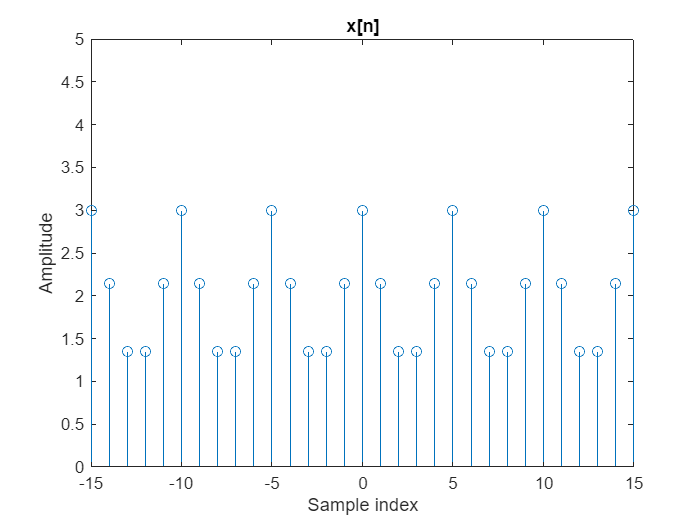

stem(n, real(x1));
axis ( [-15,15,0,5]); 
xlabel('Sample index'); 
ylabel('Amplitude');
title('x[n]');

**EX4**